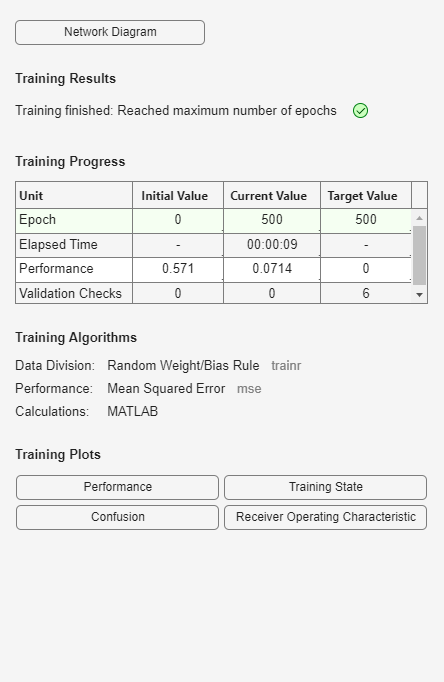

%基于LVQ网络的国家二类型判别（3个神经元）
clear                                       %清理内存
P=[79.1	76.8 80.0 78.7 73.1 75.0 75.8 66.7 71.3	70.7 72.9 69.8 69.4 66.7
99.0 99.0 99.0 99.0 96.7 74.6 96.4 99.5	98.2 91.2 99.0 92.8 77.8 53.7
23582 29605 23257 25512	12013 17719	3967 6460 4809 6006 3353 4288 4036 3041]; 
                                            %输入信号
Tc=[1 1 1 1 1 1 2 2 2 2 2 2 2 2];           %目标输出，用1、2表示
T=ind2vec(Tc);                              %输出初始分类
net=newlvq(minmax(P),3,[0.5 0.5]);          %创建学习向量量化网络
net.trainParam.epochs=500;                  %指定最大训练次数
net=train(net,P,T);                         %训练网络

Y=sim(net,P)                                %仿真结果

Y =      1     1     1     1     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     1     1     1     1     1     1     1     1


Yc=vec2ind(Y)                               %模拟的分类向量

Yc =      1     1     1     1     2     1     2     2     2     2     2     2     2     2


P_test=[78.7 78.2 70.2 68.0
99.0 96.9 97.9 82.8
20659 13943	5648 3105];                     %待判样品信号
y_test=sim(net,P_test);                     %待判样品测试
yc_test=vec2ind(y_test)                     %待判样品的分类结果

yc_test =      1     1     2     2
